# Power Series og FFT

- Data haves

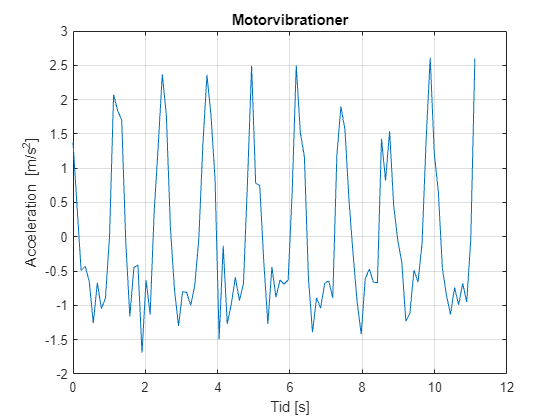

data = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...
    2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
    0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
    -0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...
    -0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...
    -0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...
    -0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...
    -0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...
    -0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...
    0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60 ];


n = length(data);

% Frekvens - givet ellers tæl toppe ellers se afl. 4
f = 9;

% Svingninger pr sekund
dt = 1/f;

% Tid for n svingninger på dt tid
tid = n*dt;

% Der laves n punkter i det tidsrum, n*dt, som svingningen foregår i
t = linspace(0, tid, n);

% Plot
plot(t, data), grid, xlabel("Tid [s]"), ylabel("Acceleration [m/s^2]"), title("Motorvibrationer")

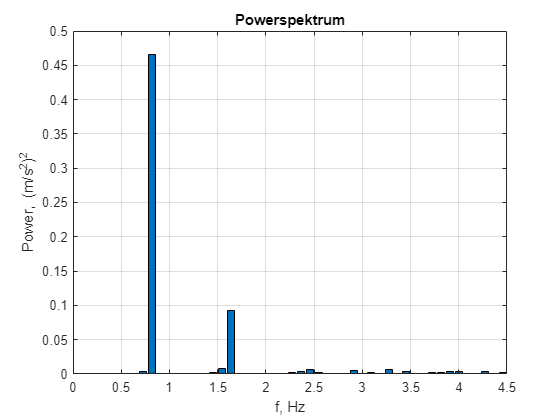




format shortg

% Maksimal frekvens
fmax = f/2;

% Svingninger pr tid
df = 1/tid;

% FFT af data
A = fft(data)/n;

% Powervektor (mm^2) % Her lægges real delen og imaginær delens sammen og forstærkes så de kun er positive
P = real(A).^2 + imag(A).^2;


f = linspace(0, n*df, n);

bar(f, P), xlim([0, fmax]), grid()

xlabel("f, Hz"), ylabel("Power, (m/s^2)^2"), title("Powerspektrum")



[m, i] = max(P)

m =       0.46545


i =     10



dom_f = f(i)

dom_f =       0.81818



max_F = find(P==max(P))

max_F =     10    92



% Her vælges første tal da andet tal blot af en gentagelse af frekvensen
% Frekvensen af det stærkeste signal bliver
f_strong = f(10)

f_strong =       0.81818


% Altså 0.9Hz